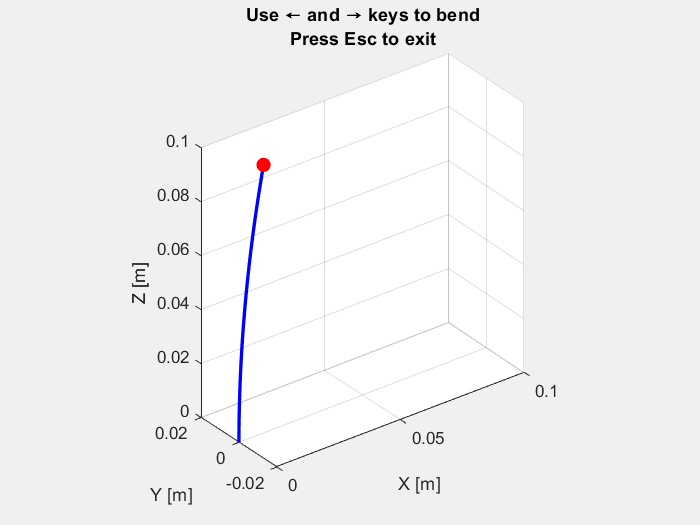

ΔL (mm): -0.06        0.03        0.03


Motor steps required per cable:


    -2     1     1



ΔL (mm): -0.12        0.06        0.06


Motor steps required per cable:


    -3     2     2



ΔL (mm): -0.18        0.09        0.09


Motor steps required per cable:


    -5     2     2



ΔL (mm): -0.24        0.12        0.12


Motor steps required per cable:


    -6     3     3



ΔL (mm): -0.3        0.15        0.15


Motor steps required per cable:


    -8     4     4



ΔL (mm): -0.36        0.18        0.18


Motor steps required per cable:


    -9     5     5



ΔL (mm): -0.42        0.21        0.21


Motor steps required per cable:


   -11     5     5



ΔL (mm): -0.48        0.24        0.24


Motor steps required per cable:


   -12     6     6



ΔL (mm): -0.54        0.27        0.27


Motor steps required per cable:


   -14     7     7



ΔL (mm): -0.6         0.3         0.3


Motor steps required per cable:


   -15     8     8



ΔL (mm): -0.66        0.33        0.33


Motor steps required per cable:


   -17     8     8



ΔL (mm): -0.72        0.36        0.36


Motor steps required per cable:


   -18     9     9



ΔL (mm): -0.78        0.39        0.39


Motor steps required per cable:


   -20    10    10



ΔL (mm): -0.84        0.42        0.42


Motor steps required per cable:


   -21    11    11



ΔL (mm): -0.9        0.45        0.45


Motor steps required per cable:


   -23    11    11



ΔL (mm): -0.96        0.48        0.48


Motor steps required per cable:


   -24    12    12



ΔL (mm): -1.02        0.51        0.51


Motor steps required per cable:


   -26    13    13



ΔL (mm): -1.08        0.54        0.54


Motor steps required per cable:


   -28    14    14



ΔL (mm): -1.14        0.57        0.57


Motor steps required per cable:


   -29    15    15



ΔL (mm): -1.2         0.6         0.6


Motor steps required per cable:


   -31    15    15



ΔL (mm): -1.26        0.63        0.63


Motor steps required per cable:


   -32    16    16



ΔL (mm): -1.2         0.6         0.6


Motor steps required per cable:


   -31    15    15



ΔL (mm): -1.14        0.57        0.57


Motor steps required per cable:


   -29    15    15



ΔL (mm): -1.08        0.54        0.54


Motor steps required per cable:


   -28    14    14



ΔL (mm): -1.02        0.51        0.51


Motor steps required per cable:


   -26    13    13



ΔL (mm): -0.96        0.48        0.48


Motor steps required per cable:


   -24    12    12



ΔL (mm): -0.9        0.45        0.45


Motor steps required per cable:


   -23    11    11



ΔL (mm): -0.84        0.42        0.42


Motor steps required per cable:


   -21    11    11



ΔL (mm): -0.78        0.39        0.39


Motor steps required per cable:


   -20    10    10



ΔL (mm): -0.72        0.36        0.36


Motor steps required per cable:


   -18     9     9



ΔL (mm): -0.66        0.33        0.33


Motor steps required per cable:


   -17     8     8



ΔL (mm): -0.6         0.3         0.3


Motor steps required per cable:


   -15     8     8



% Parameters
L = 0.1;              % Length of robot [m]
phi = 0;              % Bending direction (0 = toward +X)
kappa = 0;            % Initial curvature
dkappa = 0.2;           % Curvature step
max_kappa = 20;       % Maximum curvature
min_kappa = 0;        % Minimum curvature

% Setup figure
figure;
h = plot3(0, 0, 0, 'b', 'LineWidth', 2); hold on;
tip = plot3(0, 0, 0, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
grid on;
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
axis equal; xlim([0, 0.1]); ylim([-0.02, 0.02]); zlim([0, 0.1]);
view(3);
title({'Use ← and → keys to bend', 'Press Esc to exit'});

tip_history = [];
cable_log = [];
% Interactive control loop
while true
    w = waitforbuttonpress;
    key = get(gcf, 'CurrentCharacter');
    
    if key == 27  % ESC key to exit
        break;
    elseif key == 28  % Left arrow: unbend
        kappa = max(kappa - dkappa, min_kappa);
    elseif key == 29  % Right arrow: bend
        kappa = min(kappa + dkappa, max_kappa);
    end
    
    % Cable length change calculation
    theta_vec = [0, 2*pi/3, 4*pi/3];  % 0°, 120°, 240°
    r = 0.003;  % 3 mm radius from center
    delta_L = -kappa * r * cos(theta_vec - phi) * L;

    % Optional: display or store
    disp(['ΔL (mm): ', num2str(1000 * delta_L)]);  % Convert to mm
    cable_log(end+1, :) = delta_L;  % Store each step
    % Parameters
r_spool = 0.01;         % 10 mm spool radius [m]
step_angle = 1.8;       % degrees per step
microstepping = 8;      % 1/8 microstepping

% Example delta_L from MATLAB model (in meters)
%delta_L = [-0.001, 0.0005, 0.0002];  % example values in m for 3 cables

% Spool rotation required (radians)
theta_spool = delta_L / r_spool;

% Convert to motor steps
steps_required = (theta_spool * 180/pi) / step_angle * microstepping;

disp('Motor steps required per cable:');
disp(round(steps_required));  % round to nearest integer step

    % Recalculate shape
    s = linspace(0, L, 100);
    if kappa == 0
        x = zeros(size(s));
        y = zeros(size(s));
        z = s;
    else
        x = (1/kappa) * (1 - cos(kappa * s)) * cos(phi);
        y = (1/kappa) * (1 - cos(kappa * s)) * sin(phi);
        z = (1/kappa) * sin(kappa * s);
    end
    % After computing x, y, z
    tip_history(end+1, :) = [x(end), y(end), z(end)];

    % Update plot
    set(h, 'XData', x, 'YData', y, 'ZData', z);
    set(tip, 'XData', x(end), 'YData', y(end), 'ZData', z(end));
    drawnow;
end

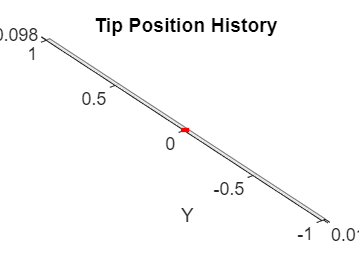

figure;
plot3(tip_history(:,1), tip_history(:,2), tip_history(:,3), 'r.-');
grid on; axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Tip Position History');